# PDF file read with OCR tool and result export to excel file

% Convert scanned document to an image
NTC_table = PDFtoImg("Thermistor-R-T_table.pdf")

NTC_table = "D:\Projects\Reflow_hot_plate\Matlab_prototyping\Thermistor\OCR_to_excel\Thermistor-R-T_table.pdf-Page1.png"

% Read and display saved image file
img = imread("NTC_table_1.png")

img = 3507×2480×3 uint8 array
img(:,:,1) =

  Columns 1 through 1,666

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25

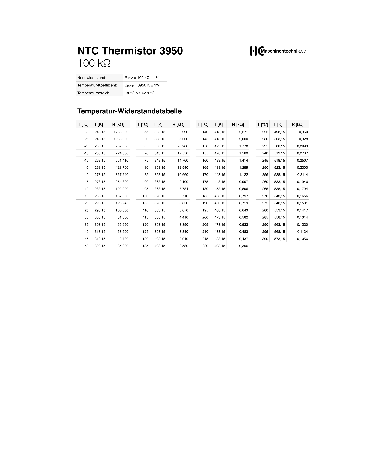

imshow(img)

N = 67 ;
T=-30;
result_T = zeros(N,1) ;
for i = 1:N
result_T(i) = T;
T=T+5;
end

for i=1:+1:4

% Select RESULT region of interest
[~,roi1] = imcrop(img);

% Display region of interest on image
Iocr = insertShape(img, "Rectangle", roi1, Color="blue", LineWidth=10);
imshow(Iocr)

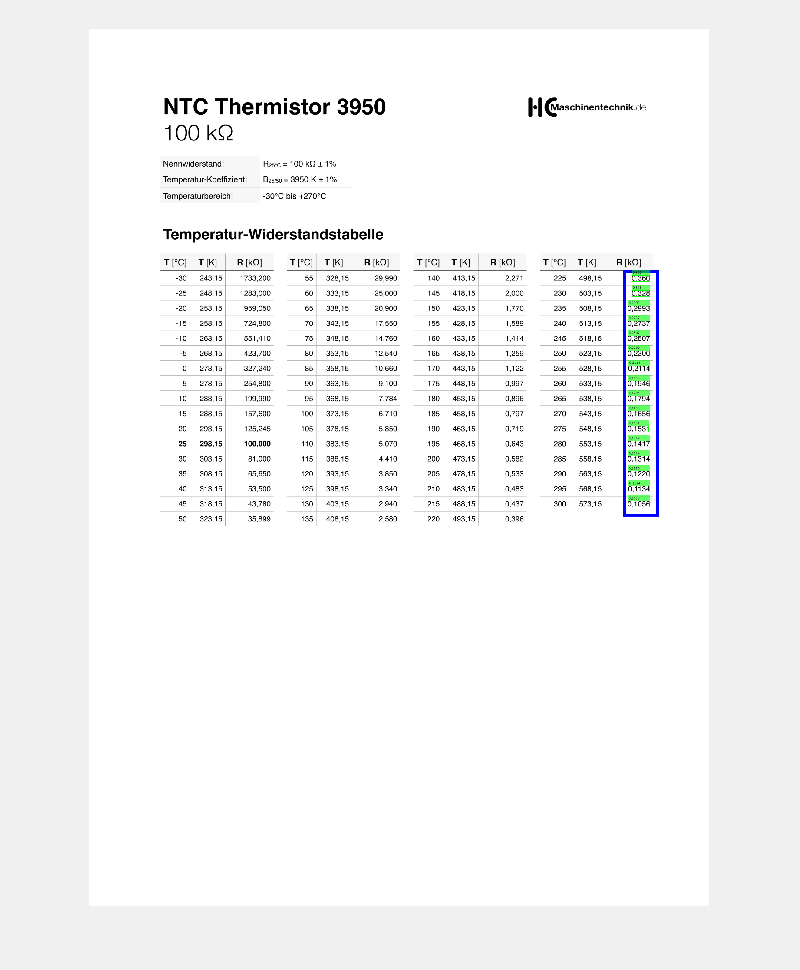

% Extract text from image
txt1 = ocr(img, roi1, CharacterSet = ".,0123456789", TextLayout = "auto");


% Find low confidence words (if any, display in yellow)
low1 = (txt1.WordConfidences < 0.6);


% Display resulting bounding boxes and words
Iocr = insertObjectAnnotation(Iocr, 'rectangle', ...
   txt1.WordBoundingBoxes(~low1, :), txt1.Words(~low1), Color = "green");
Iocr = insertObjectAnnotation(Iocr, 'rectangle', ...
   txt1.WordBoundingBoxes(low1, :), txt1.Words(low1), Color = "yellow");

% Find low confidence characthers ( display in red),
low = (txt1.CharacterConfidences < 0.6);

lab = txt1.Text(low) + " (" + round(100*txt1.CharacterConfidences(low)) + "%)";
Iocr = insertObjectAnnotation(Iocr,"rectangle", ...
    txt1.CharacterBoundingBoxes(low,:), lab,"Color","red" );
imshow(Iocr);


%txt1.Words = txt1.Words(find(~isspace(txt1.Words)))
ExtractedWords = txt1.Words;
TestName=txt1.Text;

% Remove low confidence charachters
TestName(low) = [];

TestName = splitlines(string(TestName));
TestName(TestName=="") = [];

% Convert OCR result to cell string
array = TestName.cellstr;

% Delete spaces between characters and replace comma into dot for string to
% 
array = replace(array," ","");
array = replace(array,",",".");

% Convert extracted "words" to numbers
result_part = str2double(array)

result_part = 1.0e+03 *

    1.7332
    1.2830
    0.9590
    0.7248
    0.5514
    0.4237
    0.3272
    0.2548
    0.2000
    0.1576


result_part =    29.9900
   25.0000
   20.9000
   17.5500
   14.7600
   12.5400
   10.6600
    9.1000
    7.7840
    6.7100


result_part =     2.2710
    2.0000
    1.7700
    1.5890
    1.4140
    1.2590
    1.1220
    0.9970
    0.8960
    0.7970


result_part =     0.3600
    0.3280
    0.2993
    0.2737
    0.2507
    0.2300
    0.2114
    0.1946
    0.1794
    0.1656



if i==1

    result=result_part;

else 

result=cat(1,result,result_part);

end

end


% Merge cells into one
result = result*1000;
Result_Table = cat(2,result_T,result)

Result_Table = 1.0e+06 *

   -0.0000    1.7332
   -0.0000    1.2830
   -0.0000    0.9590
   -0.0000    0.7248
   -0.0000    0.5514
   -0.0000    0.4237
         0    0.3272
    0.0000    0.2548
    0.0000    0.2000
    0.0000    0.1576


% Export to excel
xlswrite('NTC_R_T_table.xls',Result_Table)
